1. Загрузите данные **ex6data1.mat **из файла.

load('ex7data2.mat');

2. Реализуйте функцию случайной инициализации K центров кластеров.

3. Реализуйте функцию определения принадлежности к кластерам.

4. Реализуйте функцию пересчета центров кластеров.

5. Реализуйте алгоритм K-средних.

6. Постройте график, на котором данные разделены на K=3 кластеров (при помощи различных маркеров или цветов), а также траекторию движения центров кластеров в процессе работы алгоритма

load('ex7data2.mat');

K = 3;
initial_centroids = [3 3; 6 2; 8 5];

idx = findClosestCentroids(X, initial_centroids);
fprintf('Closest centroids for the first 3 examples: %d %d %d', idx(1:3));

Closest centroids for the first 3 examples: 1 3 2

centroids = computeCentroids(X, idx, K);
fprintf('Centroids computed after initial finding of closest centroids: \n %f %f \n %f %f\n %f %f' , centroids');

Centroids computed after initial finding of closest centroids: 
 2.428301 3.157924 
 5.813503 2.633656
 7.119387 3.616684

max_iters = 10;
initial_centroids = [3 3; 6 2; 8 5];

figure('visible','on'); hold on; 
plotProgresskMeans(X, initial_centroids, initial_centroids, idx, K, 1); 
xlabel('Press ENTER in command window to advance','FontWeight','bold','FontSize',14)
[~, ~] = runkMeans(X, initial_centroids, max_iters, true);

K-Means iteration 1/10...
Press enter to continue.


K-Means iteration 2/10...
Press enter to continue.
K-Means iteration 3/10...
Press enter to continue.
K-Means iteration 4/10...
Press enter to continue.
K-Means iteration 5/10...
Press enter to continue.
K-Means iteration 6/10...
Press enter to continue.
K-Means iteration 7/10...
Press enter to continue.
K-Means iteration 8/10...
Press enter to continue.
K-Means iteration 9/10...
Press enter to continue.
K-Means iteration 10/10...
Press enter to continue.


set(gcf,'visible','off'); hold off;

7. Загрузите данные **bird_small.mat **из файла.

8. С помощью алгоритма K-средних используйте 16 цветов для кодирования пикселей.

9. Насколько уменьшился размер изображения? Как это сказалось на качестве?

%  Load an image of a bird
A = double(imread('bird_small.png'));
A = A / 255; % Divide by 255 so that all values are in the range 0 - 1

% Size of the image
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16;
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
% Run K-Means
[centroids, ~] = runkMeans(X, initial_centroids, max_iters);

K-Means iteration 1/10...
K-Means iteration 2/10...
K-Means iteration 3/10...
K-Means iteration 4/10...
K-Means iteration 5/10...
K-Means iteration 6/10...
K-Means iteration 7/10...
K-Means iteration 8/10...
K-Means iteration 9/10...
K-Means iteration 10/10...


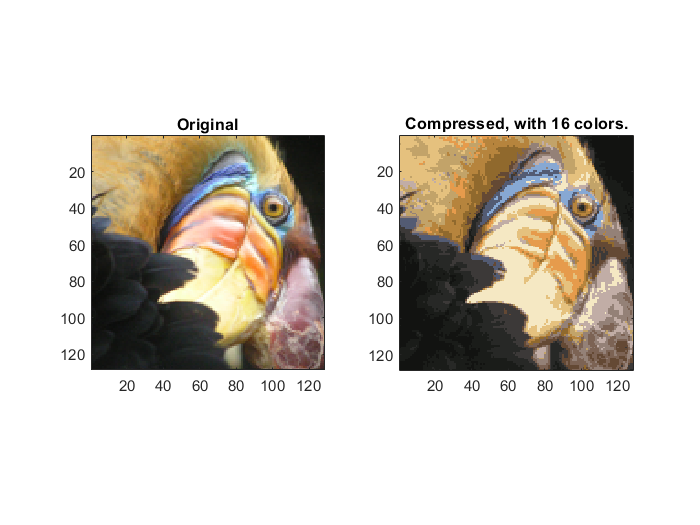

idx = findClosestCentroids(X, centroids);
X_recovered = centroids(idx,:);

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, img_size(1), img_size(2), 3);

% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));
axis square